coeff = [1 2 7 10 7 1]

coeff =      1     2     7    10     7     1


function routh_table = routh(coeff)
    n = length(coeff);
    m = ceil(n/2);                  % number of columns
    routh_table = zeros(n, m);

    % first row 
    even_coeffs = coeff(1:2:end);
    routh_table(1,1:length(even_coeffs)) = even_coeffs;

    % second row
    odd_coeffs = coeff(2:2:end);
    routh_table(2,1:length(odd_coeffs)) = odd_coeffs;

    % fill the rest of the table
    for i = 3:n
        for j = 1:m-1
            a = routh_table(i-1,1);
            b = routh_table(i-2,1);
            if abs(a) < 1e-12   % handle zero pivot case
                routh_table(i,j) = 0;
            else
                routh_table(i,j) = ((a * routh_table(i-2,j+1)) - ...
                                    (b * routh_table(i-1,j+1))) / a;
            end
        end
    end
end

R = routh(coeff)

R =     1.0000    7.0000    7.0000
    2.0000   10.0000    1.0000
    2.0000    6.5000         0
    3.5000    1.0000         0
    5.9286         0         0
    1.0000         0         0



disp('Routh Table:');

Routh Table:


disp(R);

    1.0000    7.0000    7.0000
    2.0000   10.0000    1.0000
    2.0000    6.5000         0
    3.5000    1.0000         0
    5.9286         0         0
    1.0000         0         0



function [isStable, signChanges] = check_stability(routh_table)
    % Extract first column
    first_col = routh_table(:,1);

    % Remove exact zeros (to avoid false sign flips)
    first_col = first_col(first_col ~= 0);

    % Count sign changes
    signChanges = sum(diff(sign(first_col)) ~= 0);

    % Stability condition
    isStable = (signChanges == 0);
end

[stable, changes] = check_stability(R);

if stable
    fprintf('System is stable (no RHP poles).\n');
else
    fprintf('System is unstable (%d RHP poles).\n', changes);
end

System is stable (no RHP poles).


syms K
coeff = [1 2 7 10 7 1];

% Characteristic polynomial with K
char_poly = sym(coeff);
char_poly(end) = coeff(end) + K;

% Order and number of columns
n = length(char_poly);
m = ceil(n/2);

% Initialize symbolic Routh table
R = sym(zeros(n, m));

% First two rows
odd_idx  = 1:2:n;
even_idx = 2:2:n;
R(1,1:length(odd_idx)) = char_poly(odd_idx);
R(2,1:length(even_idx)) = char_poly(even_idx);

% Fill remaining rows
for i = 3:n
    for j = 1:m-1
        a = R(i-1,1);
        b = R(i-2,1);
        if a == 0
            R(i,j) = 0;
        else
            R(i,j) = simplify((a*R(i-2,j+1) - b*R(i-1,j+1))/a);
        end
    end
end

disp('Routh Table (symbolic):');

Routh Table (symbolic):


disp(R);

$$\left(\begin{array}{ccc} 1 & 7 & 7\\ 2 & 10 & K+1\\ 2 & \frac{13}{2}-\frac{K}{2} & 0\\ \frac{K}{2}+\frac{7}{2} & K+1 & 0\\ -\frac{K^{2}+2\,K-83}{2\,\left(K+7\right)} & 0 & 0\\ K+1 & 0 & 0 \end{array}\right)$$


% --- Stability conditions: first column > 0 ---
first_col = simplify(R(:,1));

disp('First column of Routh table:');

First column of Routh table:


disp(first_col);

$$\left(\begin{array}{c} 1\\ 2\\ 2\\ \frac{K}{2}+\frac{7}{2}\\ -\frac{K^{2}+2\,K-83}{2\,\left(K+7\right)}\\ K+1 \end{array}\right)$$


% Convert to numeric functions of K
first_col_fun = matlabFunction(first_col);

% Sweep K values to check stability
Kvals = -10:0.01:20;   
stable_idx = arrayfun(@(k) all(double(first_col_fun(k)) > 0), Kvals);

% Extract contiguous stable interval(s)
stable_K = Kvals(stable_idx);
if isempty(stable_K)
    disp('No stability range found.');
else
    Kmin = min(stable_K);
    Kmax = max(stable_K);
    fprintf('System is stable for %.3f < K < %.3f\n', Kmin, Kmax);
end

System is stable for -0.990 < K < 8.160


G = tf(1, coeff);
poles_open = pole(G)

poles_open =   -0.1034 + 2.3044i
  -0.1034 - 2.3044i
  -0.8035 + 0.6028i
  -0.8035 - 0.6028i
  -0.1863 + 0.0000i


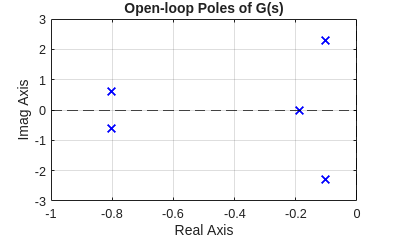

figure;
plot(real(poles_open),imag(poles_open),'bx','MarkerSize',8,'LineWidth',1.5);
yline(0,'k--'); xline(0,'k--');
xlabel('Real Axis'); ylabel('Imag Axis');
title('Open-loop Poles of G(s)');
grid on;

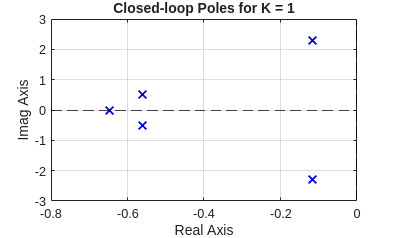

T = feedback(G,1);
poles_closed = pole(T);

figure;
plot(real(poles_closed), imag(poles_closed), 'bx','MarkerSize',8,'LineWidth',1.5);
yline(0,'k--'); xline(0,'k--');
xlabel('Real Axis'); ylabel('Imag Axis');
title('Closed-loop Poles for K = 1');
grid on;

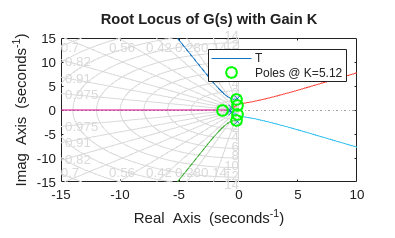

Kmin = 0.0;
Kmax = 5.123;   

% Root locus plot
figure;
rlocus(T); hold on;
title('Root Locus of G(s) with Gain K');
xlabel('Real Axis'); ylabel('Imag Axis'); grid on;

Tmin = feedback(Kmin*T, 1);
poles_min = pole(Tmin);
plot(real(poles_min), imag(poles_min), 'ro', 'MarkerSize', 8, ...
    'LineWidth', 1.5, 'DisplayName', sprintf('Poles @ K=%.2f', Kmin));

Tmax = feedback(Kmax*T, 1);
poles_max = pole(Tmax);
plot(real(poles_max), imag(poles_max), 'go', 'MarkerSize', 8, ...
    'LineWidth', 1.5, 'DisplayName', sprintf('Poles @ K=%.2f', Kmax));

legend show;

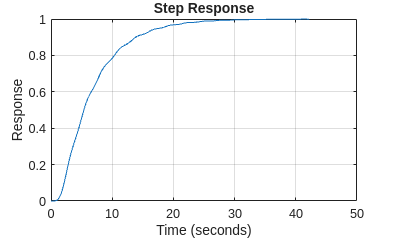

[y, tOut] = step(G);
figure;
plot(tOut, y);
title('Step Response');
xlabel('Time (seconds)');
ylabel('Response');
grid on;

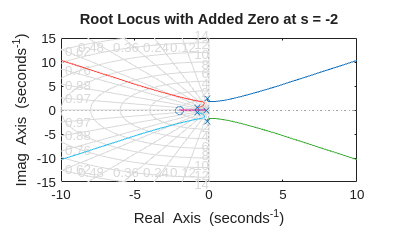

num_with_zero = [1 2];   % added zero at -2
den = coeff;
G_with_zero = tf(num_with_zero, den);

figure;
rlocus(G_with_zero);
title('Root Locus with Added Zero at s = -2');
xlabel('Real Axis'); ylabel('Imag Axis'); grid on;